addpath(genpath("ptv"));
addpath(genpath("mutils"));
addpath(genpath("results"));

source_imgs = zeros(1024, 1280, 27);
for i = 1:27
    wavelength = 430 + i*10;
% source_imgs = zeros(1024, 1280, 20);
% for i = 1:20
%     wavelength = 500 + i*10;
    filename = ['data/multispectral2/image sample ' num2str(wavelength) 'nm 1.png'];
    img = imread(filename);
    img = im2gray(img);
    source_imgs(:, :, i) = img;
end
source_imgs = sqrt(double(reshape(source_imgs, [size(source_imgs, 1), size(source_imgs, 2), 1, 1, size(source_imgs,3)])));
%sqrt is a dirty trick to get rid of highlights
source_imgs = source_imgs ./ max(max(source_imgs, [], 1), [], 2);

% source_imgs = zeros(256, 256, 3);
% source_imgs(:, :, 1) = im2gray(imread("data/curr/moving.png"));
% source_imgs(:, :, 2) = im2gray(imread("data/curr/moving.png"));
% source_imgs(:, :, 3) = im2gray(imread("data/curr/moving.png"));
% source_imgs = sqrt(double(reshape(source_imgs, [size(source_imgs, 1), size(source_imgs, 2), 1, 1, size(source_imgs,3)])));
% source_imgs = source_imgs ./ max(max(source_imgs, [], 1), [], 2);


% target_img = imread("data/registered/r_spectral.png");
% target_img = imread("data/curr/fixed.png");
% target_img = im2gray(target_img);
% target_img = target_img ./ max(max(target_img, [], 1), [], 2);

opts = [];
opts.pix_resolution = [4, 4];
opts.metric = 'nuclear';

opts.grid_spacing = [10, 10];
opts.isoTV = 5e-3;

opts.spline_order = 1;
opts.max_iters = 70;

opts.display = 'off';

opts.border_mask = 6;
opts.k_down = 0.6;


tic
% [voldef_pl, Tmin_pl,  Kmin_pl] = ptv_register(source_imgs, target_img, opts);
[voldef_pl, Tmin_pl,  Kmin_pl] = ptv_register(source_imgs, [], opts);

fmin = 1.432709e+06 (9)
fmin = 5.159296e+05 (8)
fmin = 2.677003e+05 (7)
fmin = 1.449619e+05 (6)
fmin = 7.108742e+04 (5)
fmin = 4.031100e+04 (4)
fmin = 2.343620e+04 (3)
fmin = 1.396467e+04 (2)
fmin = 8.373320e+03 (1)


toc

Elapsed time is 435.005391 seconds.


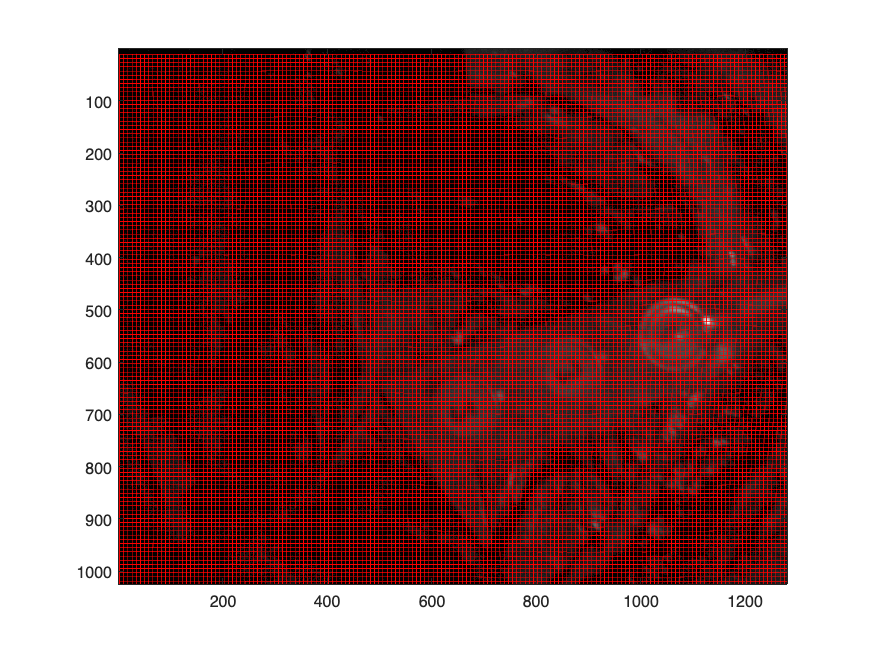

%%
imgs_exp = [];
for i = 1 : size(source_imgs, 3)
    hold off;
    imagesc(squeeze(source_imgs(:,:,1,1,i)));
    colormap gray;
    hold on;
    plot_wiremesh(squeeze(Tmin_pl(:,:, 1, :, i)), 8, 'r-');
    daspect([1,1,1]);
    F = getframe;
    imgs_exp = cat(4, imgs_exp, double(F.cdata));
end

res_images = zeros(1024, 1280, 3, 3);
% res_images = zeros(256, 256, 3, 3);
sq_source_imgs = squeeze(source_imgs);
sq_voldef_pl = squeeze(voldef_pl);
for i = 1:3
    res_images(:, :, 1, i) = sq_source_imgs(:, :, i) * 0.5;
    res_images(:, :, 2, i) = sq_source_imgs(:, :, i) * 0.5;
    res_images(:, :, 3, i) = sq_voldef_pl(:, :, i) * 0.5;
end

savegif('results/msi_track2.gif', squeeze([imgs_exp]/250), 1/10);
savegif('results/msi_register2.gif', squeeze([source_imgs, voldef_pl]), 1/10);
savegif('results/msi_merged2.gif', squeeze([res_images]), 1/10);